# OCR

Let's try out GPT-4o with an easy example of code copied with a simple printscreen (win+shift+s). You can also use the Windows snipping tool to grab images on your screen. This requires a function from File Exchange[1] (it doesn't support MATLAB Online):

[1] [IMCLIPBOARD - File Exchange - MATLAB Central](https://www.mathworks.com/matlabcentral/fileexchange/28708-imclipboard)

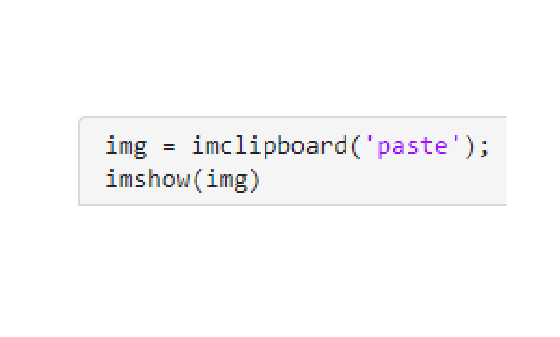

img = imclipboard('paste');
imshow(img)

imwrite(img,"printscreen.png")
chatVision("Extract the text from the image, return only the text.","printscreen.png")

ans =     "```
     img = imclipboard('paste');
     imshow(img)
     ```"


code = chatVision("Extract the code from the image, return only the code without markdown formating.","printscreen.png")

code =     "img = imclipboard('paste');
     imshow(img)"
